## Load data

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses'
cd Groundwater\HistWaterLevel_SupPlot\data\input\

load('BR1.mat')
load('BR2.mat')
load('BLM37_complete.mat')
load('BLM45_complete.mat')
load('BLM93C_complete.mat')
load('BLM93_complete.mat')
load("BLM16_complete.mat")

BLM93.Properties.RowTimes(103562) = '07/25/21 07:15:00 PM';
BLM93.Properties.RowTimes(103563) = '09/09/21 07:30:00 PM';
BLM93.WaterLevelBelowSurface_m(103562) = -0.039;
BLM93.WaterLevelBelowSurface_m(103563) = 0.04;

BLM16 = removevars(BLM16, 'WellID_BLM');
BLM37 = removevars(BLM37, {'WellID_BLM'});
BLM93 = removevars(BLM93, {'WellID_BLM'});
BLM93C = removevars(BLM93C,"WellID_BLM");
BLM45 = removevars(BLM45, {'WellID_BLM'});

load('BLM37_AirPresCor.mat')
load('BLM45_AirPresCor.mat')
load('BLM93C_AirPresCor.mat')
load('BLM93_AirPresCor.mat')
load("BLM16_AirPresCor.mat")

%Add in manual water level measurements for BLM93
BLM93.Properties.RowTimes(32969) = '07/25/21 07:15:00 PM';
BLM93.Properties.RowTimes(32968) = '09/09/21 07:30:00 PM';
BLM93.WaterLevelBelowSurface_m(32969) = -0.039;
BLM93.WaterLevelBelowSurface_m(32968) = 0.04;

%%Remove Nonnumeric values
% BLM16 = removevars(BLM16, 'WellID_BLM');
% BLM37 = removevars(BLM37, {'WellID_BLM'});
% BLM93 = removevars(BLM93, {'WellID_BLM'});
% BLM93C = removevars(BLM93C,"WellID_BLM");
% BLM45 = removevars(BLM45, {'WellID_BLM'});
BR1 = removevars(BR1, {'WellID_BLM', 'DataSource','MeasurementMethod','OtherID','townrangeLocalWellNumber','WaterTDSmgL','WaterDensitykgm3','WaterTemperatureC','WaterElevationm'});
BR2 = removevars(BR2, {'WellID_BLM','DataSource','MeasurementMethod','townrangeLocalWellNumber','USGSID'});

## Average Monthly Groundwater Levels

BLM16monthly = retime(BLM16, 'monthly', 'mean');
BLM93monthly = retime(BLM93, 'monthly', 'mean');
BLM93Cmonthly = retime(BLM93C, 'monthly', 'mean');
BLM37monthly = retime(BLM37, 'monthly', 'mean');
BLM45monthly = retime(BLM45, 'monthly', 'mean');
BR1monthly = retime(BR1, 'monthly', 'mean');
BR2monthly = retime(BR2, 'monthly', 'mean');

BLM16monthly.month = datenum(month(BLM16monthly.Date_Time_MDT));
BLM93Cmonthly.month = datenum(month(BLM93Cmonthly.Date_Time_MDT));
BLM93monthly.month = datenum(month(BLM93monthly.Date_Time_MDT));
BLM37monthly.month = datenum(month(BLM37monthly.Date_Time_MDT));
BLM45monthly.month = datenum(month(BLM45monthly.Date_Time_MDT));
BR1monthly.month = datenum(month(BR1monthly.Date_Time_MDT));
BR2monthly.month = datenum(month(BR2monthly.Date_Time_MDT));

## Measured water depth

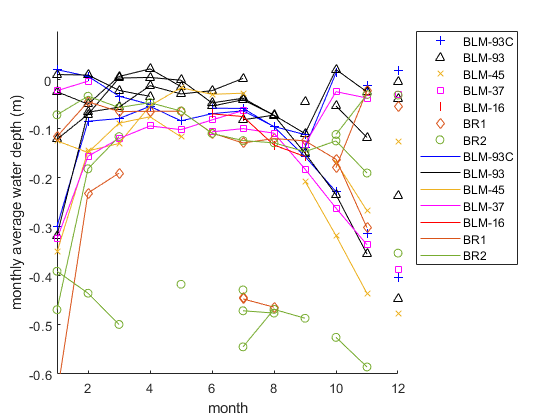

figure
hold on 
scatter(BLM93Cmonthly.month, -BLM93Cmonthly.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor, '+','blue', 'DisplayName','BLM-93C')
scatter(BLM93monthly.month, -BLM93monthly.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,'^','black', 'DisplayName','BLM-93')
scatter(BLM45monthly.month, -BLM45monthly.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,'x', 'DisplayName','BLM-45')
scatter(BLM37monthly.month, -BLM37monthly.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,'square','magenta', 'DisplayName','BLM-37')
scatter(BLM16monthly.month, -BLM16monthly.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor, '|','red', 'DisplayName','BLM-16')

scatter(BR1monthly.month, -BR1monthly.EquivalentHead_HaliteSaturated_BelowSurf_m,'diamond','MarkerEdgeColor',[0.8500 0.3250 0.0980], 'DisplayName','BR1')
scatter(BR2monthly.month, -BR2monthly.EquivalentHead_HaliteSaturated_BelowSurf_m,'o','MarkerEdgeColor',[0.4660 0.6740 0.1880], 'DisplayName','BR2')
legend('location', 'bestoutside')
%Replace month 12 with NaN to make a gap in plot
BR2monthly = sortrows(BR2monthly,'month','descend');
BR2monthly.month(1:12) = NaN;
BR2monthly = sortrows(BR2monthly,'Date_Time_MDT','ascend');

BR1monthly = sortrows(BR1monthly,'month','descend');
BR1monthly.month(1:16) = NaN;
BR1monthly = sortrows(BR1monthly,'Date_Time_MDT','ascend');

BLM93monthly = sortrows(BLM93monthly,'month','descend');
BLM93monthly.month(1:4) = NaN;
BLM93monthly = sortrows(BLM93monthly,'Date_Time_MDT','ascend');

BLM93Cmonthly = sortrows(BLM93Cmonthly,'month','descend');
BLM93Cmonthly.month(1:4) = NaN;
BLM93Cmonthly = sortrows(BLM93Cmonthly,'Date_Time_MDT','ascend');

BLM37monthly = sortrows(BLM37monthly,'month','descend');
BLM37monthly.month(1:2) = NaN;
BLM37monthly = sortrows(BLM37monthly,'Date_Time_MDT','ascend');

BLM45monthly = sortrows(BLM45monthly,'month','descend');
BLM45monthly.month(1:3) = NaN;
BLM45monthly = sortrows(BLM45monthly,'Date_Time_MDT','ascend');


plot(BLM93Cmonthly.month, -BLM93Cmonthly.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,'color','blue', 'DisplayName','BLM-93C')
plot(BLM93monthly.month, -BLM93monthly.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,'color','black', 'DisplayName','BLM-93')
plot(BLM45monthly.month, -BLM45monthly.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor, 'DisplayName','BLM-45')
plot(BLM37monthly.month, -BLM37monthly.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,'color','magenta', 'DisplayName','BLM-37')
plot(BLM16monthly.month, -BLM16monthly.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,'color','red', 'DisplayName','BLM-16')
plot(BR1monthly.month, -BR1monthly.EquivalentHead_HaliteSaturated_BelowSurf_m, 'color',[0.8500 0.3250 0.0980],'DisplayName','BR1')
plot(BR2monthly.month, -BR2monthly.EquivalentHead_HaliteSaturated_BelowSurf_m,'color',[0.4660 0.6740 0.1880], 'DisplayName','BR2')

xlabel('month')
ylabel('monthly average water depth (m)')
xlim([1,12])
% xlim([5,8])
ylim([-0.6,0.1])
% ylim([-0.1,0.1])
cd ..\output\
print('HistoricalWaterLevelSupPlot', '-bestfit','-dpdf') %'-bestfit' -fillpage